BEREN ÜNVEREN 221101006 ELE 71 PROJESI

studentId = 221101006;
rng(studentId);

a = randi(4);
b = randi(4);
c = randi(4);
d = randi(4);
e = randi(4);
f = randi(4);

fprintf('a = %d\n', a);

a = 1


fprintf('b = %d\n', b);

b = 3


fprintf('c = %d\n', c);

c = 2


fprintf('d = %d\n', d);

d = 4


fprintf('e = %d\n', e);

e = 1


fprintf('f = %d\n', f);

f = 2


 T = a + b + c + d + e + f  temel dönemli x(t) sinyali çıkarımı:

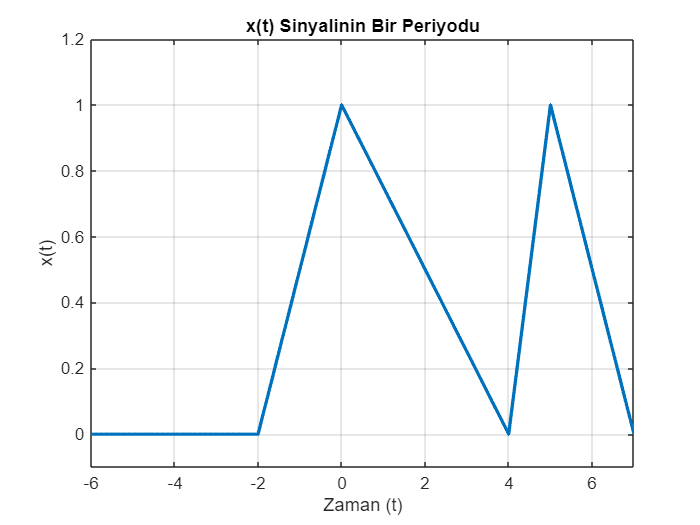

dt = 0.01;
t = -a-b-c:dt:d+e+f;
xt = zeros(size(t));
idx = 1:length(t);
xt(idx)=(((t(idx)>=-c & t(idx)<0) .* ((1/c)*t(idx)+1)) + ... %x(t)=(1/c)t+1
        ((t(idx)>=0 & t(idx)<d) .* ((-1/d)*t(idx)+1)) + ... %x(t)=(-1/d)t+1
        ((t(idx)>=d & t(idx)<d+e) .* ((1/e)*(t(idx)-d))) + ... %x(t)=(1/e)(t-d)
        ((t(idx)>=d+e & t(idx)<=d+e+f) .* (1-(1/f)*(t(idx)-(d+e)))) ... %x(t)=(1/f)(t-d-e)
        );

figure;
plot(t, xt, 'LineWidth', 2);
title('x(t) Sinyalinin Bir Periyodu');
xlabel('Zaman (t)');
ylabel('x(t)');
grid on;
ylim([-0.1 1.2]);
xlim([-a-b-c d+e+f])

x(t) Fourier katsayıları: abs(ak) k'ya göre, k=-30,30 için stem komutu ile, a0 ve k!=0 hesabı ayrı. analiz ve grafik.

ak = (1/T) ∫ x(t)e^(-jkω₀t) dt  -> burada parcalı integral olacak

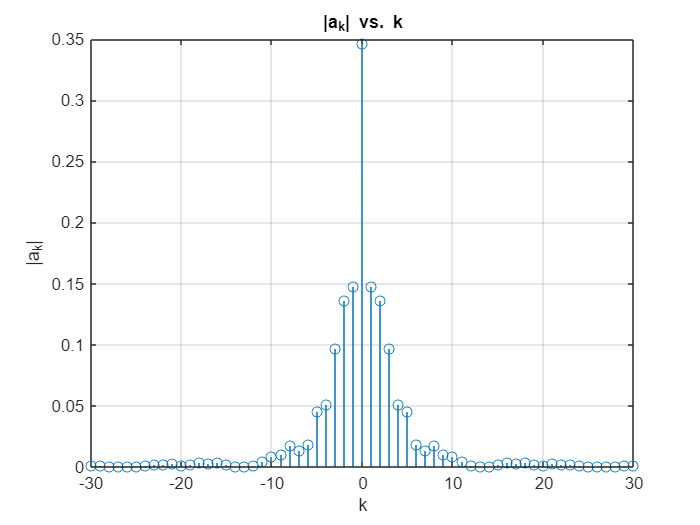

T = a+b+c+d+e+f;
w0 = 2*pi/T;
integrand = @(t, k)(((t>=-c & t<0) .* ((1/c)*t+1)) + ... %x(t)=(1/c)t+1
                    ((t>=0 & t<d) .* ((-1/d)*t+1)) + ... %x(t)=(-1/d)t+1
                    ((t>=d & t<d+e) .* ((1/e)*(t-d))) + ... %x(t)=(1/e)(t-d)
                    ((t>=d+e & t<=d+e+f) .* (1-(1/f)*(t-(d+e)))) ... %x(t)=(1/f)(t-d-e)
                    ).* exp(-1j*k*w0*t);
k_vals = -30:30;
ak = zeros(size(k_vals));
ak(k_vals == 0) = (0.5 * (c+d) + 0.5 * (e+f))/T; %ak=0 durumu
k_nonzero_indices = find(k_vals ~= 0);

for i = 1:length(k_nonzero_indices)
    idx = k_nonzero_indices(i);
    ki = k_vals(idx);
    integral_result = integral(@(t) integrand(t, ki), -c, d+e+f);
    ak(idx) = (1/T) * integral_result;
end

figure;
stem(k_vals, abs(ak));
title('|a_k| vs. k');
xlabel('k');
ylabel('|a_k|');
grid on;
xlim([-30 30]);